InOutの閾値を決めるための検証（中心からの距離のヒストグラム）

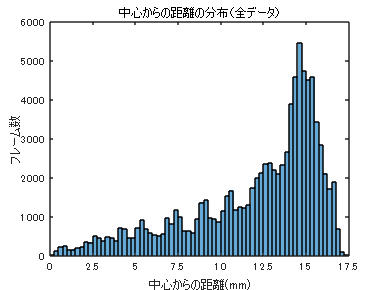

clear all
close all

% データの読み込み
cd Data\
Info = readtable("FileInformation.csv");

% 使わない段の削除
Info((Info.StayRate==0 | Info.StayRate==1),:)=[];

% 距離データの読み込み
DistAll = [];
DistPhero = [];
Dist1 = []; % においありエリア
Dist0 = []; % においなしエリア
DistS1 = [];
DistS0 = [];
DistD1 = [];
DistD0 = [];
DistNonPhero = [];
for i = 1:height(Info) 
    Data = readtable(append(Info.FileName(i), "_CalcData.csv"));
    DistAll = [DistAll;Data.Distance];
    if Info.SDN(i)~="N"
        DistPhero = [DistPhero;Data.Distance];
        Dist1 = [Dist1;Data.Distance(Data.x<=0)];
        Dist0 = [Dist0;Data.Distance(Data.x>0)];
        if Info.SDN(i)=="S"
            DistS1 = [DistS1;Data.Distance(Data.x<=0)];
            DistS0 = [DistS0;Data.Distance(Data.x>0)];
        else
            DistD1 = [DistD1;Data.Distance(Data.x<=0)];
            DistD0 = [DistD0;Data.Distance(Data.x>0)];
        end
    else
        DistNonPhero = [DistNonPhero;Data.Distance];
    end
end

%データをピクセルからmmになおす
DistAll = DistAll.*(35/1000);
DistPhero = DistPhero.*(35/1000);
Dist1 = Dist1 .*(35/1000);
Dist0 = Dist0 .* (35/1000);
DistS1 = DistS1 .*(35/1000);
DistS0 = DistS0 .* (35/1000);
DistD1 = DistD1 .*(35/1000);
DistD0 = DistD0 .* (35/1000);
DistNonPhero = DistNonPhero.*(35/1000);

%グラフ化
figure
histogram(DistAll,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（全データ）")

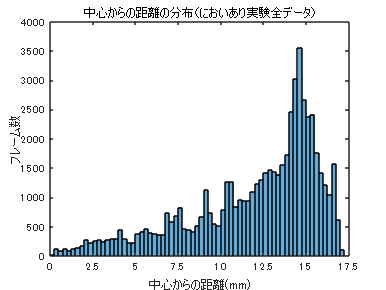


figure
histogram(DistPhero,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（においあり実験全データ）")

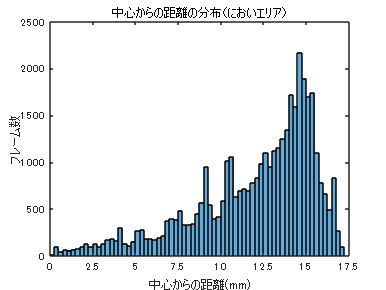


figure
histogram(Dist1,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（においエリア）")

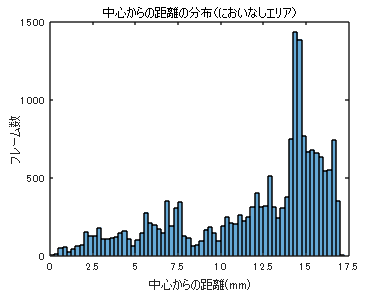


figure
histogram(Dist0,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（においなしエリア）")

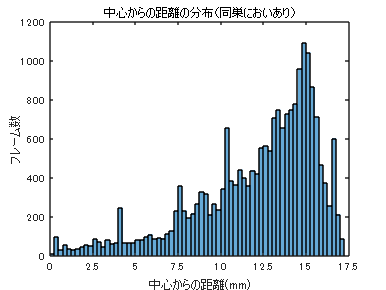


figure
histogram(DistS1,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（同巣においあり）")

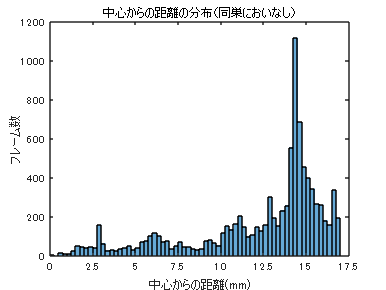


figure
histogram(DistS0,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（同巣においなし）")

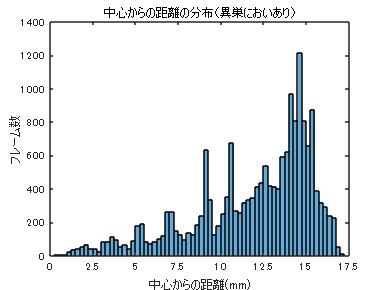


figure
histogram(DistD1,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（異巣においあり）")

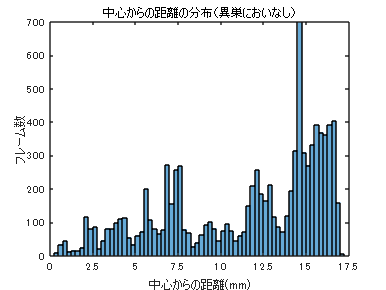


figure
histogram(DistD0,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（異巣においなし）")

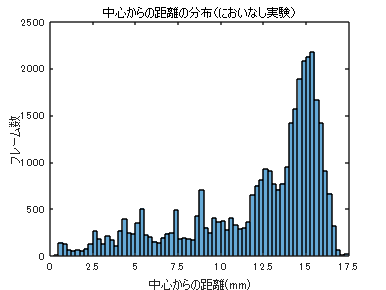


figure
histogram(DistNonPhero,0:0.25:17.5)
xlim([0 17.5])
xticks([0 2.5 5 7.5 10 12.5 15 17.5]);
xlabel("中心からの距離(mm)")
ylabel("フレーム数")
title("中心からの距離の分布（においなし実験）")


cd ..\

境界からの距離のヒストグラム

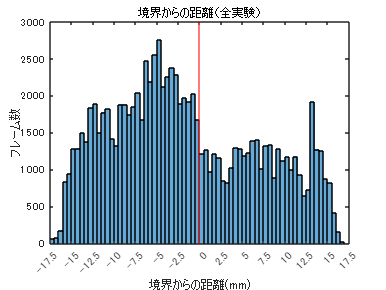

clear all
close all

% データの読み込み
cd Data\
Info = readtable("FileInformation.csv");

% 使わない段の削除
Info((Info.StayRate==0 | Info.StayRate==1),:)=[];

% 距離データの読み込み
DistBorderAll = [];
DistBorderPhero = [];
DistBorderS = [];
DistBorderD = [];
DistBorderN = [];
for i = 1:height(Info) 
    Data = readtable(append(Info.FileName(i), "_CalcData.csv"));
    DistBorderAll = [DistBorderAll;Data.x];
    if Info.SDN(i)=="S"
        DistBorderPhero = [DistBorderPhero;Data.x];
        DistBorderS = [DistBorderS;Data.x];
    elseif Info.SDN(i)=="D"
        DistBorderPhero = [DistBorderPhero;Data.x];
        DistBorderD = [DistBorderD;Data.x];
    elseif Info.SDN(i)=="N"
        DistBorderN = [DistBorderN;Data.x];
    end
end

%データをピクセルからmmになおす
DistBorderAll = DistBorderAll.*(35/1000);
DistBorderPhero = DistBorderPhero.*(35/1000);
DistBorderS = DistBorderS.*(35/1000);
DistBorderD = DistBorderD.*(35/1000);
DistBorderN = DistBorderN.*(35/1000);

%グラフ化
figure
histogram(DistBorderAll,-17.5:0.5:17.5)
xline(0, "red")
xlim([-17.5 17.5])
xticks(-17.5:2.5:17.5);
xlabel("境界からの距離(mm)")
ylabel("フレーム数")
title("境界からの距離（全実験）")

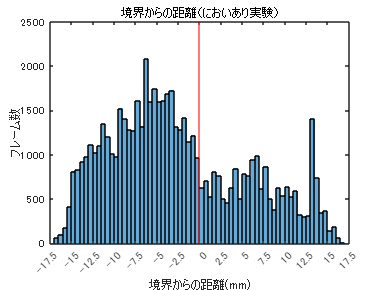


figure
histogram(DistBorderPhero,-17.5:0.5:17.5)
xline(0, "red")
xlim([-17.5 17.5])
xticks(-17.5:2.5:17.5);
xlabel("境界からの距離(mm)")
ylabel("フレーム数")
title("境界からの距離（においあり実験）")

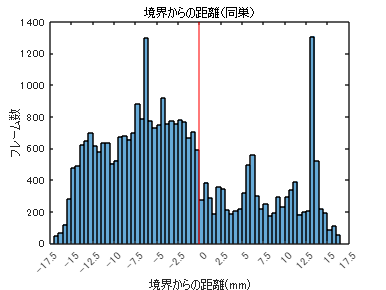


figure
histogram(DistBorderS,-17.5:0.5:17.5)
xline(0, "red")
xlim([-17.5 17.5])
xticks(-17.5:2.5:17.5);
xlabel("境界からの距離(mm)")
ylabel("フレーム数")
title("境界からの距離（同巣）")

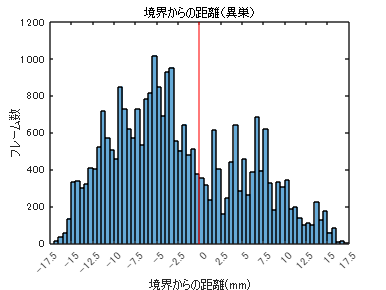


figure
histogram(DistBorderD,-17.5:0.5:17.5)
xline(0, "red")
xlim([-17.5 17.5])
xticks(-17.5:2.5:17.5);
xlabel("境界からの距離(mm)")
ylabel("フレーム数")
title("境界からの距離（異巣）")

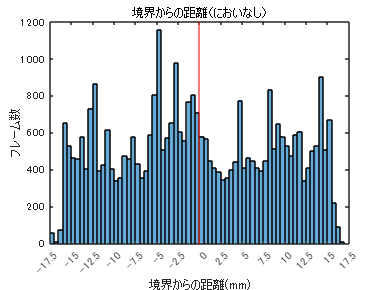


figure
histogram(DistBorderN,-17.5:0.5:17.5)
xline(0, "red")
xlim([-17.5 17.5])
xticks(-17.5:2.5:17.5);
xlabel("境界からの距離(mm)")
ylabel("フレーム数")
title("境界からの距離（においなし）")


% 割合化

% histogramの面積を1に
DistBorderAll = DistBorderAll ./ length(DistBorderAll);
DistBorderPhero = DistBorderPhero./length(DistBorderPhero);
DistBorderS = DistBorderS ./ length(DistBorderS);
DistBorderD = DistBorderD ./ length(DistBorderS);
DistBorderN = DistBorderN ./ length(DistBorderS);


cd ..\